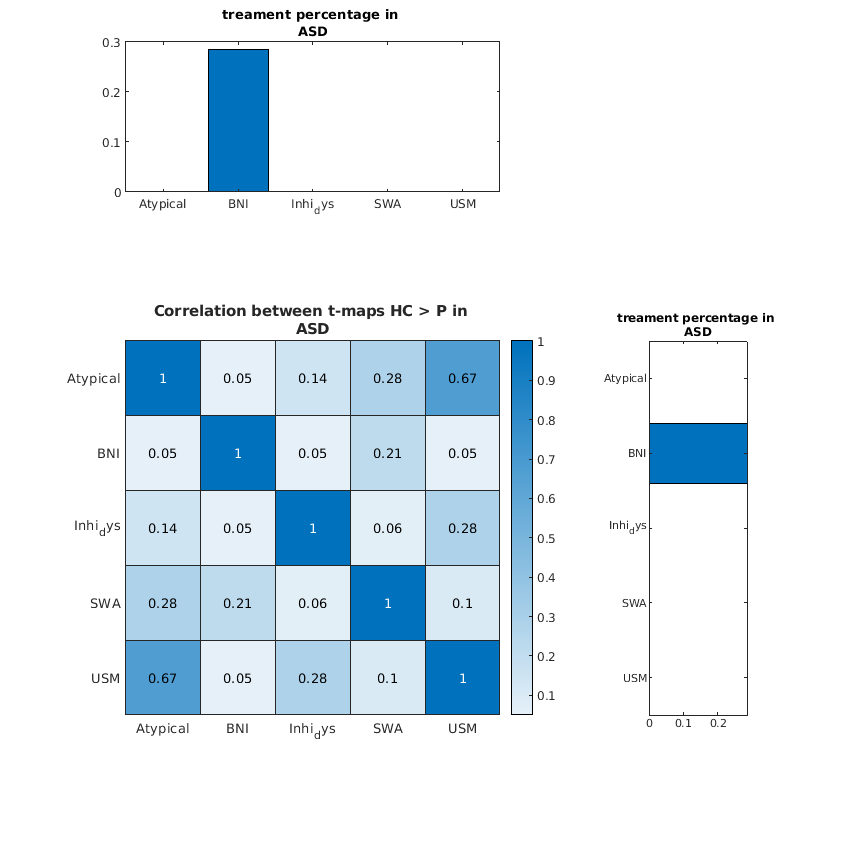

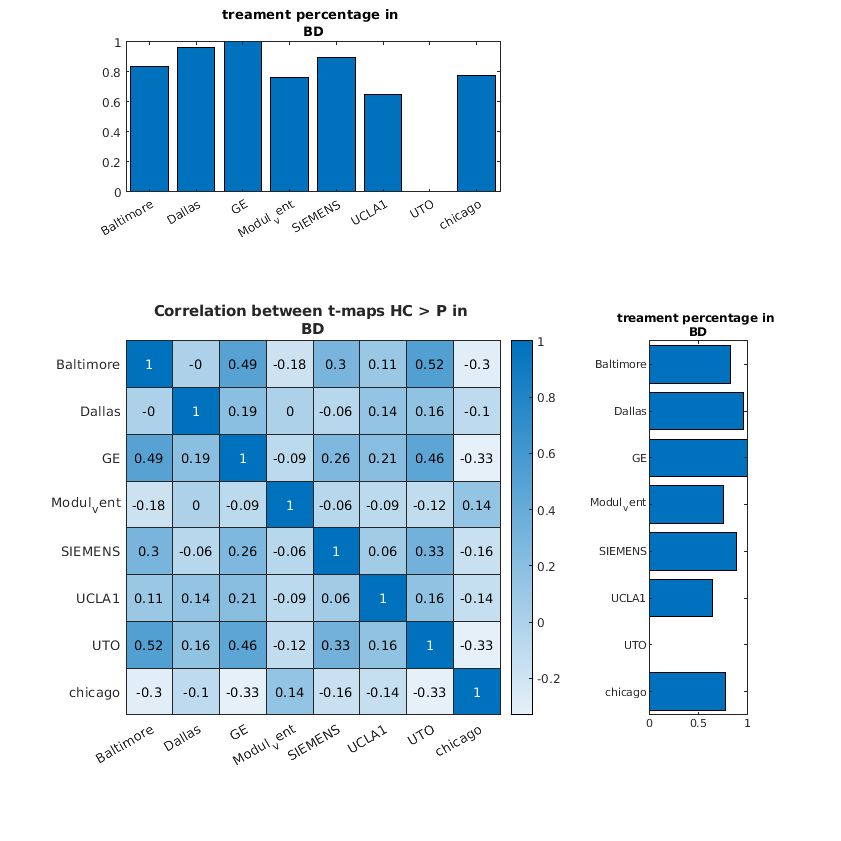

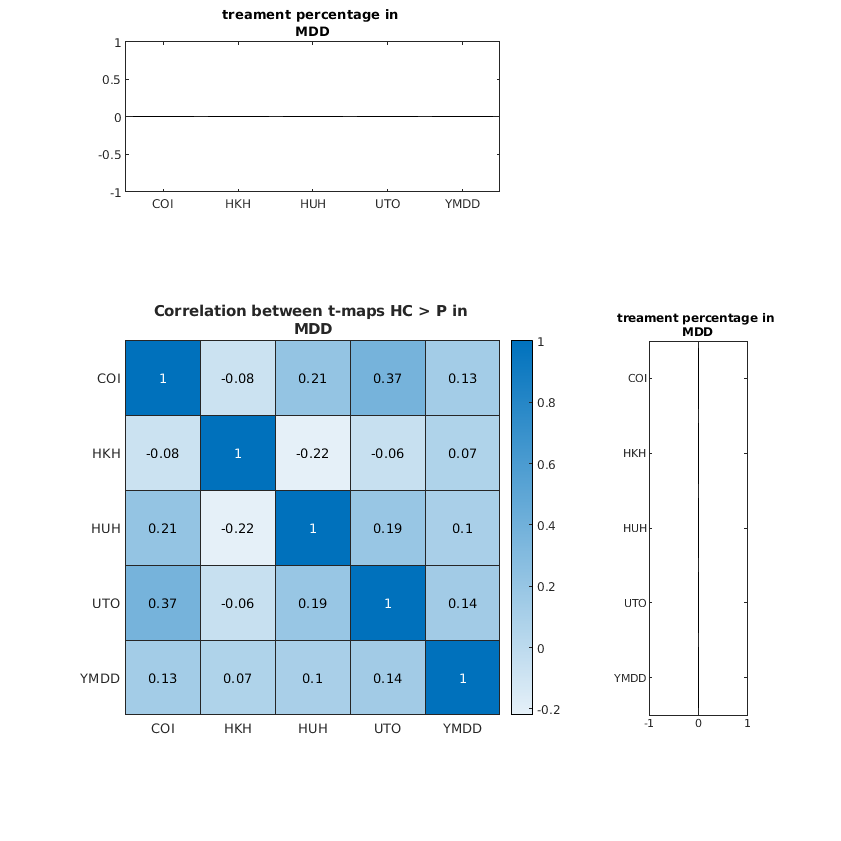

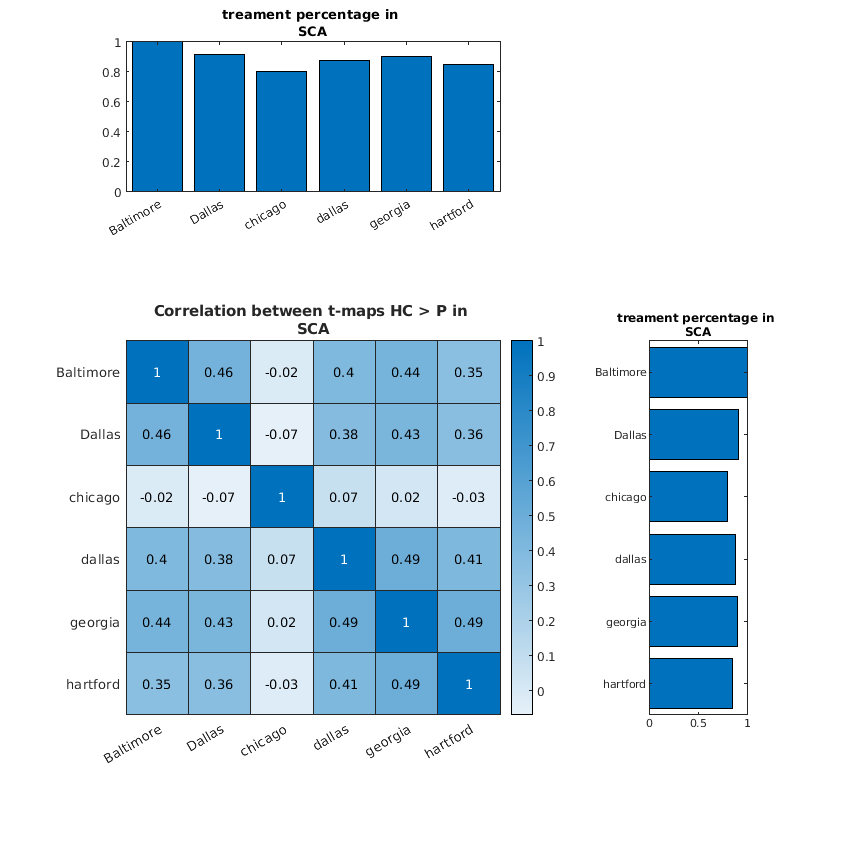

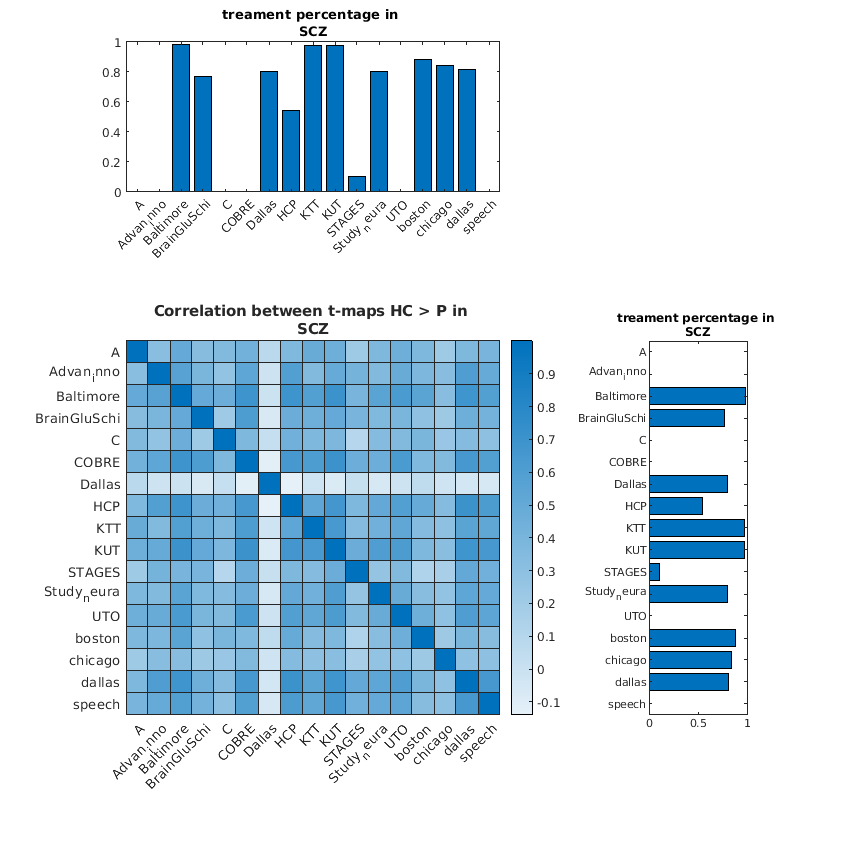

clear all
close all

iCOMBAT = 1;
smoothKernel = 8;

if iCOMBAT == 1
    address = ['derivatives/s',num2str(smoothKernel),'COMBAT/'];
else
    address = ['derivatives/s',num2str(smoothKernel),'/'];
end

metadata = readtable(['/home/trangc/kg98/trangc/VBM/data/derivatives/s',num2str(smoothKernel),'COMBAT/metadata_extended.csv']);

diagnosisString = unique(metadata.diagnosis_string);
diagnosisString = diagnosisString(~ismember(diagnosisString,'HC'));
nDiag = length(diagnosisString);

for iDiag = 1:nDiag


plot_corr_tmap_treatment(address, metadata, diagnosisString(iDiag))   

    clear t1All t2All nPC nSex ageMean ageStd
end

warning('off','last')